# **Statistics - Lab 1**

clear; close all;

# **Question 1**

**Write a function that can generate 100 samples from a normal distribution with mean 10 and standard deviation 2; use function normrnd. Plot the histogram for the sample data*****, *****and adjust the number of bins so that it resembles a normal distribution; use function hist(x, number of bins) Generate again 100 samples and plot a new histogram. Repeat this 5 times (that is, 5 different experiments). Why do the histograms look different on each of the 5 experiments? **

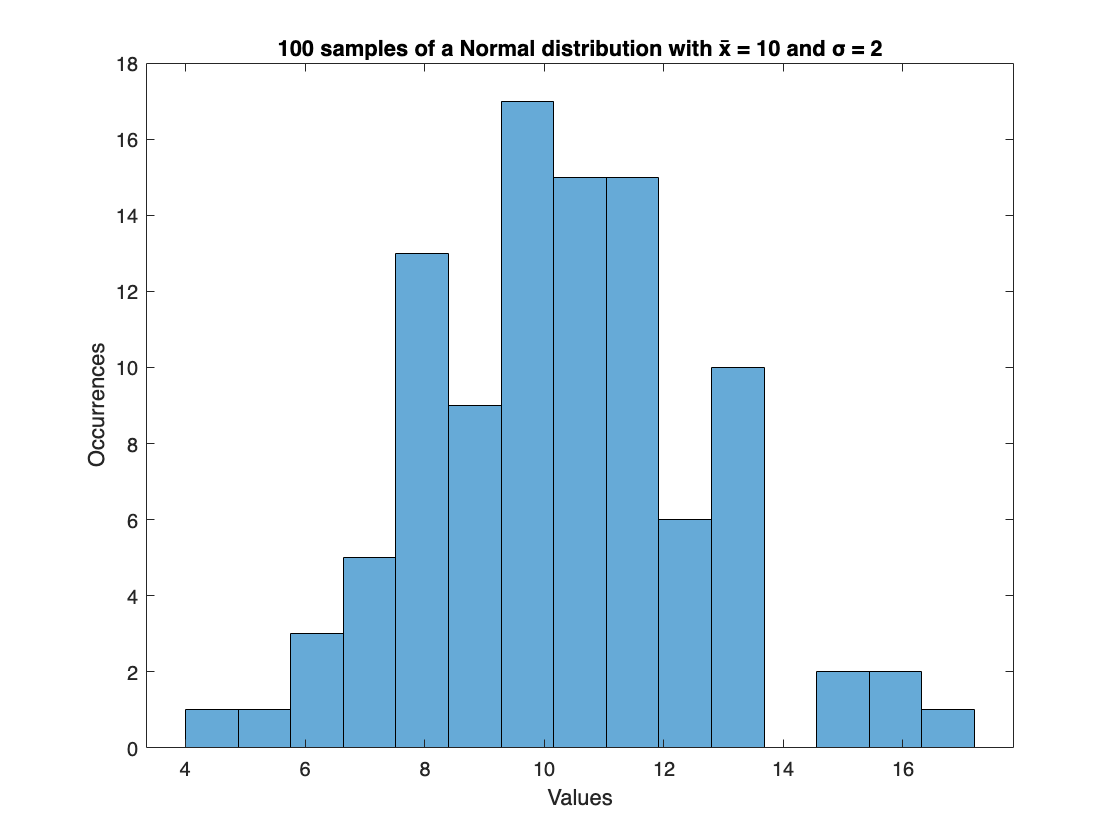

% Definition of essential variables for the simulations
n_of_samples = 100;      % Number of samples that each simulation will have
mean = 10;               % Mean of the Normal distribution
std_dev = 2;             % Standard Deviation of the Normal distribution

% First sampling and its histogram
sample1 = normal(n_of_samples, mean, std_dev);
plot_histogram(sample1, 15);

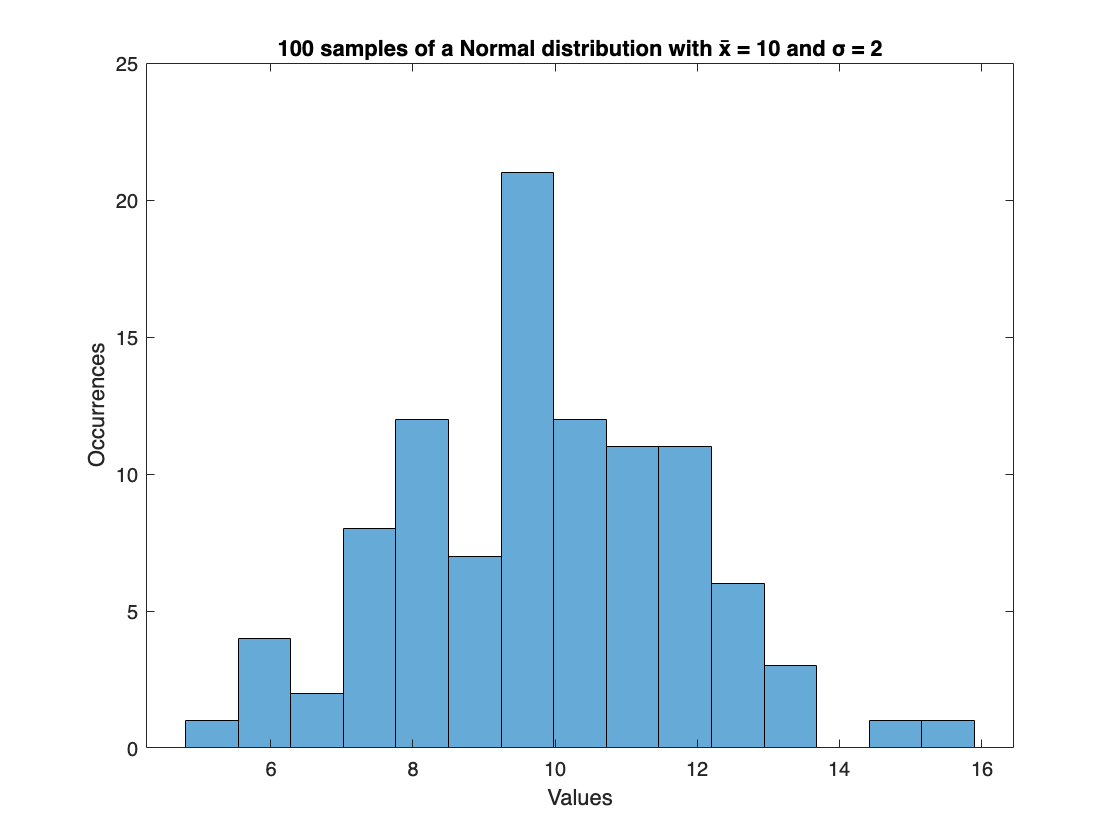

% Second sampling and its histogram
sample2 = normal(n_of_samples, mean, std_dev);
plot_histogram(sample2, 15);

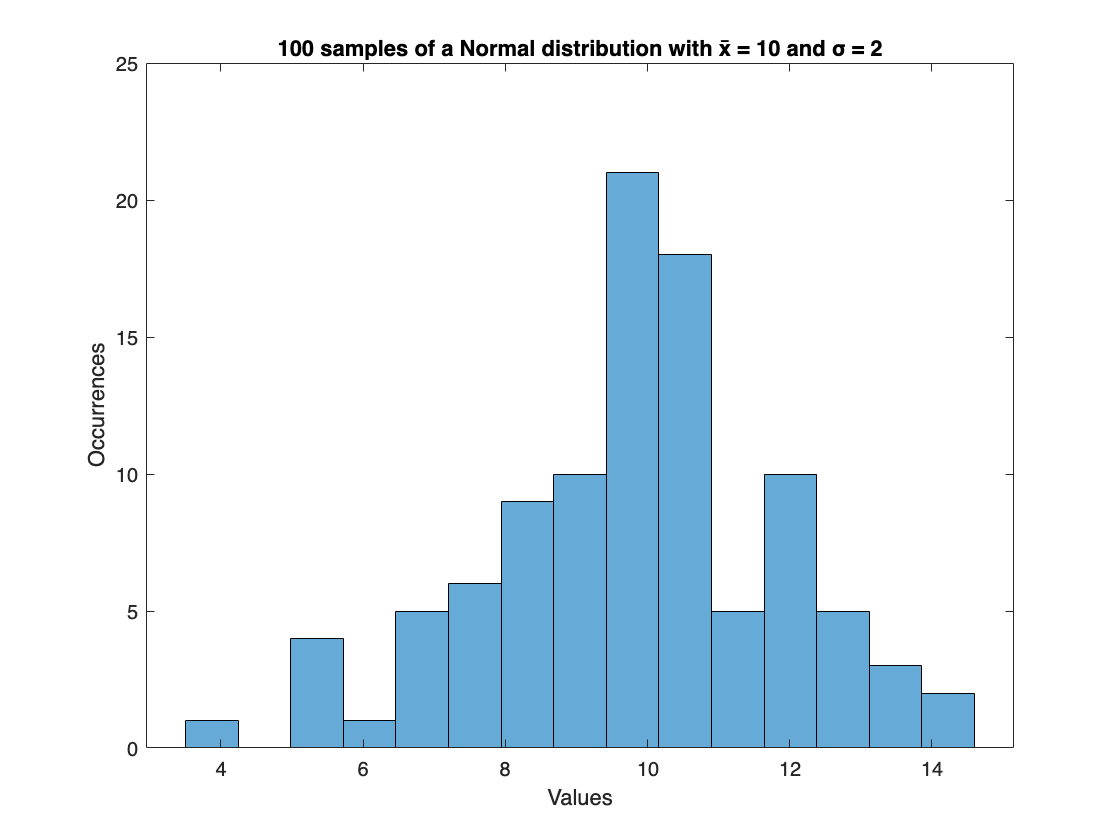

% Third sampling and its histogram
sample3 = normal(n_of_samples, mean, std_dev);
plot_histogram(sample3, 15);

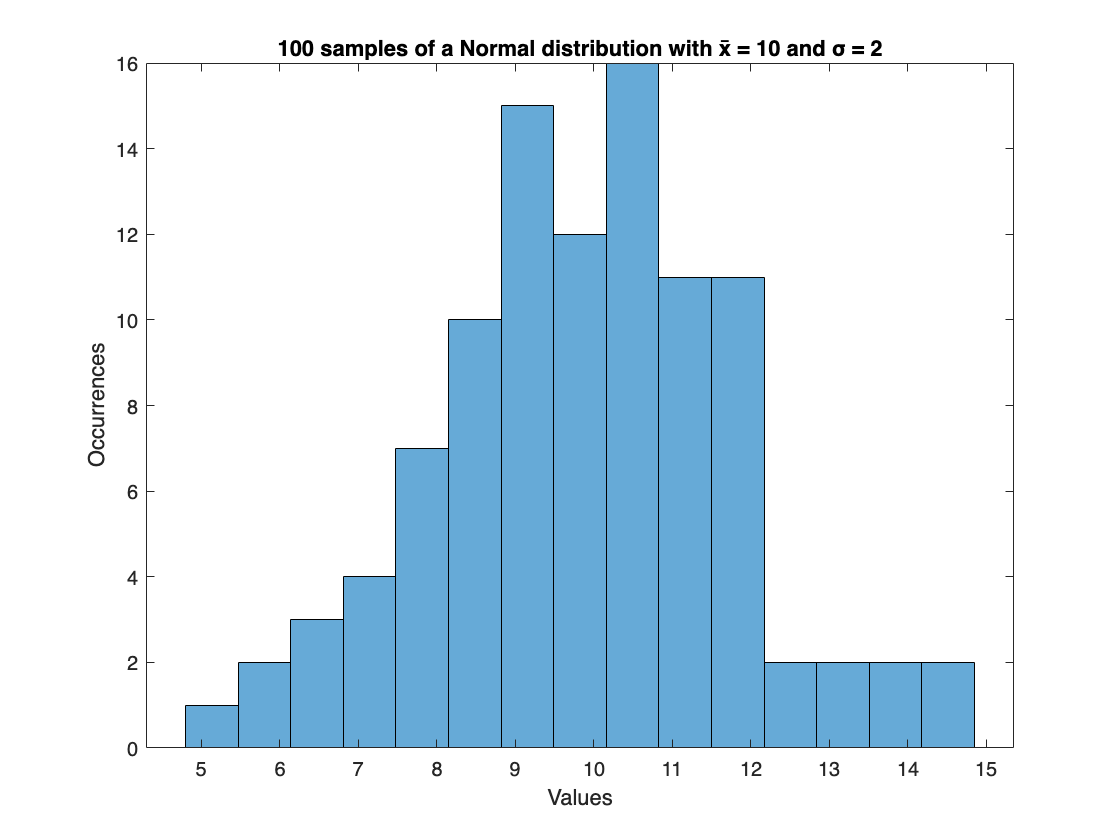

% Fourth sampling and its histogram
sample4 = normal(n_of_samples, mean, std_dev);
plot_histogram(sample4, 15);

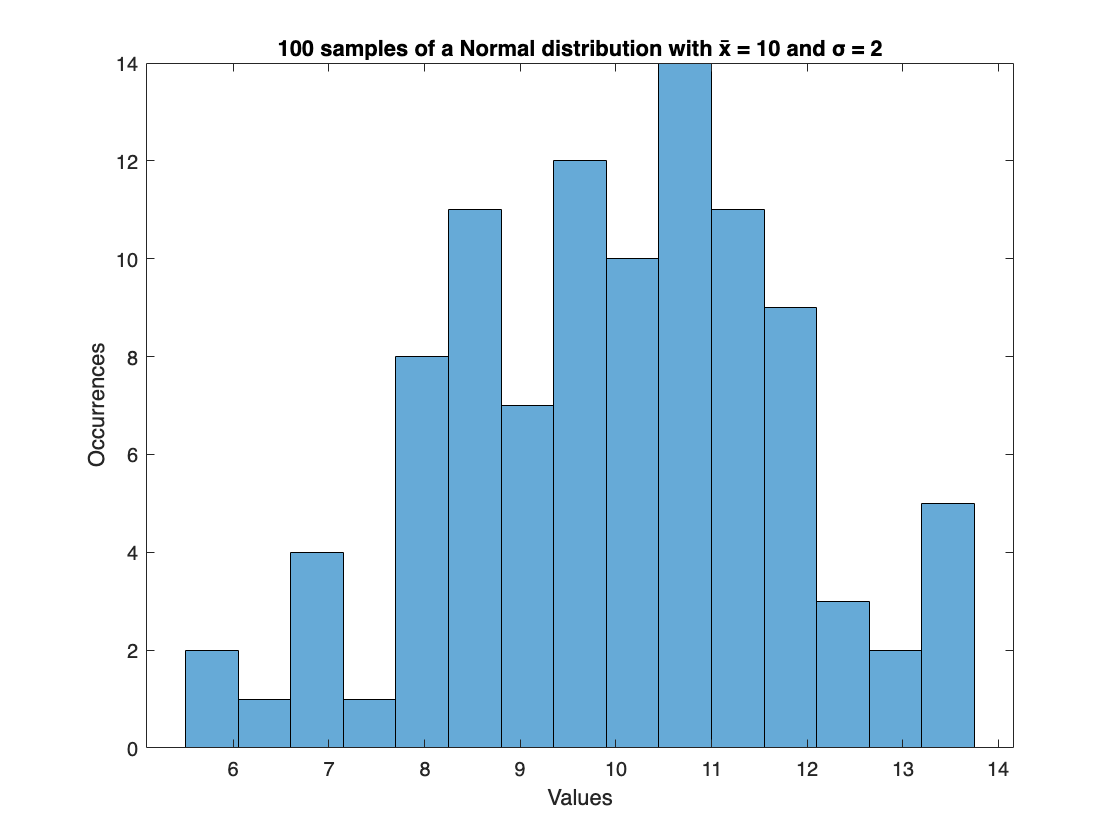

% Fifth sampling and its histogram
sample5 = normal(n_of_samples, mean, std_dev);
plot_histogram(sample5, 15);

The histograms above are different because they represent different samples that have been randomly generated. 

Even though all the samples have been generated from a given distribution with equal parameters, they are still random samples. If we look at the histograms, we can see that the occurrence of the values always tends to be around the mean. 

In the case of having a greater number of samples, for example, we would see histograms that are more similar to each other, since as we increase the number of samples generated, the histograms would look more similar to each other.

# **Question 2**

**Write a Matlab function to calculate the mean value of a sample; compare your result to the mean() function in Matlab. Do not use *****sum()***** in your function. Use the custom-made function to compute the sample mean in the previous examples in each of the 5 experiments. Why does the sample mean differ in each experiment?**

% Computing the sample mean of the first sample
mean_sample1 = sample_mean(sample1, 1);

The computed mean using the formula is equal to 10.2462
The computed mean using mean() function is equal to 10.2462


% Computing the sample mean of the second sample
mean_sample2 = sample_mean(sample2, 1);

The computed mean using the formula is equal to 9.8546
The computed mean using mean() function is equal to 9.8546


% Computing the sample mean of the third sample
mean_sample3 = sample_mean(sample3, 1);

The computed mean using the formula is equal to 9.7784
The computed mean using mean() function is equal to 9.7784


% Computing the sample mean of the fourth sample
mean_sample4 = sample_mean(sample4, 1);

The computed mean using the formula is equal to 9.8705
The computed mean using mean() function is equal to 9.8705


% Computing the sample mean of the fifth sample
mean_sample5 = sample_mean(sample5, 1);

The computed mean using the formula is equal to 10.0311
The computed mean using mean() function is equal to 10.0311


As discussed earlier, as the generated values are random, despite following a specific distribution, the mean is a value that depends on the observations, therefore, it will vary depending on the values that are generated. 

Despite this, most of the time the calculated means will be close to the theoretical mean $\mu =10$.

# **Question 3**

**Write a function to calculate the sample standard deviation; compare your result to the std() function in Matlab. Use the custom-made function to compute the sample standard deviation in the previous examples in each of the 5 experiments. Why does the sample std differ in each experiment?**

% Computing the sample standard deviation of the first sample
stdev_sample1 = sample_stdev(sample1, 1);

The computed Standard Deviation using the formula is equal to 2.3248
The computed Standard Deviation using std() function is equal to 2.3248


% Computing the sample standard deviation of the second sample
stdev_sample2 = sample_stdev(sample2, 1);

The computed Standard Deviation using the formula is equal to 2.0101
The computed Standard Deviation using std() function is equal to 2.0101


% Computing the sample standard deviation of the third sample
stdev_sample3 = sample_stdev(sample3, 1);

The computed Standard Deviation using the formula is equal to 2.0326
The computed Standard Deviation using std() function is equal to 2.0326


% Computing the sample standard deviation of the fourth sample
stdev_sample4 = sample_stdev(sample4, 1);

The computed Standard Deviation using the formula is equal to 1.884
The computed Standard Deviation using std() function is equal to 1.884


% Computing the sample standard deviation of the fifth sample
stdev_sample5 = sample_stdev(sample5, 1);

The computed Standard Deviation using the formula is equal to 1.7472
The computed Standard Deviation using std() function is equal to 1.7472


After having observed the behavior of the means in different samples, we now see that the standard deviation behaves similarly. 

Even though all the samples have been generated randomly from a distribution with certain parameters, in all of them, they will have a more or less dispersed value within a range of around 2.

# **Question 4**

**We want to compare the histogram of the data with the pdf of the normal distribution with the maximum likelihood estimate (MLE) of the parameters that characterizes the distribution of the data. Do not use call to *****mle(). *****Represent graphically the probability density function (pdf) of the normal distribution with the MLE on top of the histogram from one of the above experiments. The data histogram should be normalized such that the y axis represents a density estimate and thus it can be compared to the pdf (hint: check options in function *****histogram()*****).**

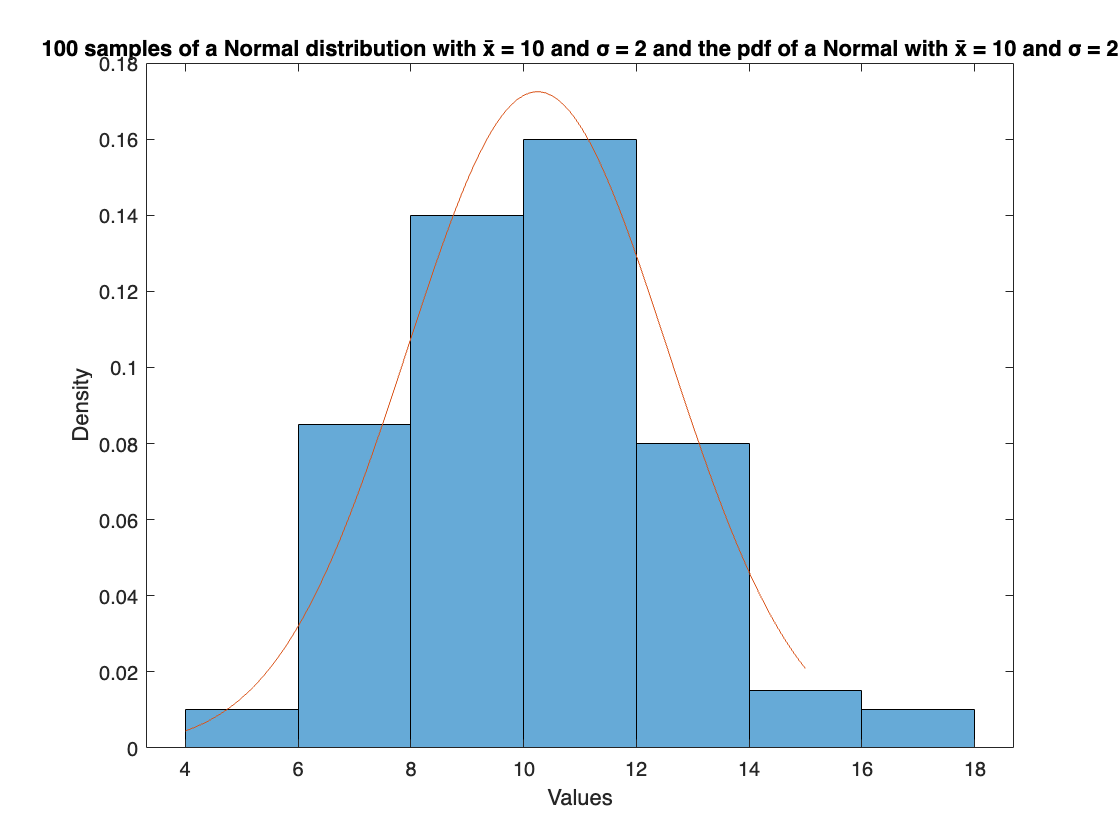

% First, we estimate the mean and the standard distribution using the MLE method
[mu1, sigma1] = max_likelihood(sample1);

% Then, we plot the histogram of the sample and the PDF of the Normal distribution 
max_likelihood_histogram(sample1, mu1, sigma1);

# **Question 5**

**Write a function to calculate the confidence intervals for the value of the distribution mean, at a confidence level 1-*****α***** indicated below. Use the function norminv (inverse of the cumulative of a standard normal) to calculate the critical *****Z***** values.**

% Confidence interval for the first sample and a = 0.5
[i1, s1] = confidence_interval(0.5, sample1, 1);

Interval for α = 0.5: [10.2462, 10.2462]


% Confidence interval for the first sample and a = 0.1
[i2, s2] = confidence_interval(0.1, sample1, 1);

Interval for α = 0.1: [9.9482, 10.5441]


% Confidence interval for the first sample and a = 0.05
[i3, s3] = confidence_interval(0.05, sample1, 1);

Interval for α = 0.05: [9.8638, 10.6286]


% Confidence interval for the first sample and a = 0.01
[i4, s4] = confidence_interval(0.01, sample1, 1);

Interval for α = 0.01: [9.7053, 10.787]


# **Question 6**

**Fill in the following table for different significance levels *****α*****for one of the experiments using the function generated in Question 5.**


$$\alpha =0\ldotp 50\;\;\;\;\to \;\;\;\;\left\lbrack 10\ldotp 2462,10\ldotp 2462\right\rbrack$$



$$\alpha =0\ldotp 10\;\;\;\;\to \;\;\;\;\left\lbrack 9\ldotp 9482,10\ldotp 5441\right\rbrack$$



$$\alpha =0\ldotp 05\;\;\;\;\to \;\;\;\;\left\lbrack 9\ldotp 8638,10\ldotp 6286\right\rbrack$$



$$\alpha =0\ldotp 01\;\;\;\;\to \;\;\;\;\left\lbrack 9\ldotp 7053,10\ldotp 787\right\rbrack$$


As we can see in the previous results, using an $\alpha$ value close to 1 implies having a lower confidence level, so fewer values will be considered within the interval.

# **Question 7**

**Generate 100 experiments from the same normal distribution as above (mean 10 and std 2), each with sample size 100. Write a function to count the number of experiments where the theoretical value of the mean *****µ *****of the normal distribution falls inside the confidence intervals. **

% Number of times that the theoretical mean falls inside of the confidence interval with a = 0.2
inside(0.2, mean);

The number of times the theoretical mean falls within the interval with α = 0.2 is 62


% Number of times that the theoretical mean falls inside of the confidence interval with a = 0.1
inside(0.1, mean);

The number of times the theoretical mean falls within the interval with α = 0.1 is 83


% Number of times that the theoretical mean falls inside of the confidence interval with a = 0.05
inside(0.05, mean);

The number of times the theoretical mean falls within the interval with α = 0.05 is 97


% Number of times that the theoretical mean falls inside of the confidence interval with a = 0.01
inside(0.01, mean);

The number of times the theoretical mean falls within the interval with α = 0.01 is 97



$$\alpha =0\ldotp 20\;\;\;\;\to \;\;\frac{62}{100}$$



$$\alpha =0\ldotp 10\;\;\;\;\to \;\;\frac{83}{100}$$



$$\alpha =0\ldotp 05\;\;\;\;\to \;\;\frac{97}{100}$$



$$\alpha =0\ldotp 01\;\;\;\;\to \;\;\frac{97}{100}$$


As we can see in the previous results, and following the same line as in the results presented in the previous exercise, the higher the value of $\alpha$, the fewer values will be accepted within the interval, and therefore, the less likely it will be that the mean theory is inside.

# **Question 8**

**Consider the null hypothesis that the expected value of the data x is the mean 10 and std 2. Test the null hypothesis against the alternative hypothesis that the mean is smaller than 10 at significance level *****α***** = 0.05 (use the sample of just one experiment). Repeat the test if the alternative hypothesis is that the mean is larger than 9. Give the result of your tests.**

% Testing the null hypothesis Ho: mu = 10 versus the alternative hypothesis Ha: mu < 10
test_1(n_of_samples, 10, 2, 0.05);

As Z belongs to the acceptation area (Z ϵ A), we accept the null hypothesis.


% Testing the null hypothesis Ho: mu = 10 versus the alternative hypothesis Ha: mu > 9
test_2(n_of_samples, 9, 2, 0.05);

As Z belongs to the acceptation area (Z ϵ A), we accept the null hypothesis.


## Give the result of your tests.

In this practice, we have tested some statistics basic concepts using a programming language such as MATLAB.

In the first exercise, 5 experiments have been simulated with data from a Normal distribution with parameters $\mu =10$ and $\sigma =2$, which have been collected in arrays of 100 positions. For all of them, we have calculated 2 statistics: the sample mean $\bar{X}$, and the sample standard deviation $s$, and we have compared the histograms of all of them. We have seen that they are not equal, although they have a very similar range of values.

Then, we have used the Maximum Likelihood estimator to estimate the parameters of the distribution of one of the samples previously generated. Using the normpdf function, we have compared the histogram of the sample with the theoretical pdf of the Normal $N\left(10,2\right)$.

Later, we have calculated 4 confidence intervals using 4 different values for $\alpha$: $\alpha =0\ldotp 5$, $\alpha =0\ldotp 1$, $\alpha =0\ldotp 05$ and $\alpha =0\ldotp 01$, and using them, we have seen the direct effects of the confidence level on the confidence intervals.

Afterwards, we have applied the confidence intervals theory simulating 100 experiments as we have done in Exercise 1, and seeing how many times the theoretical mean falls inside of that interval.

Finally, we have applied the theory of hypothesis testing to do 2 tests over a sample, and using code, see if the null hypothesis is rejected or accepted.

# **Functions**

***normal(n, m, s)***

This function takes as input 3 values:

- n: the number of samples that should be generated.

- m: the mean of the Normal distribution that we will generate.

- s: the standard deviation of the Normal distribution that we will generate.

Then, using the *normrnd* function, we will store the 100 samples in an array, named *x*, where each position will contain the value of the generated sample.

Once those samples are stored, we will return the array for later use.

function x = normal(n, m, s)
    x = zeros(1,n);
    for i = 1:n
        x(i) = normrnd(m, s);
    end
end

***plot_histogram(x, nbins)***

This function takes as input 2 values:

- x: the array of samples that we should display in the histogram.

- n_bins: number of bins that our histogram should have.

Then, using the *histogram* function, we will show the histogram of the sample with *nbins* number of bins.

function [] = plot_histogram(x, nbins)
    histogram(x, nbins);
    title("100 samples of a Normal distribution with x̄ = 10 and σ = 2");
    xlabel("Values");
    ylabel("Occurrences");
end

***sample_mean(x, bin)***

This function takes as input 2 values:

- x: the array of samples.

- bin: a variable to determine if we want to print the result of the computed mean.

In this function, we have implemented the formula


$$\bar{X} =\frac{X_1 +\ldotp \ldotp \ldotp +X_n }{n}$$


Creating a variable *sum*, we will calculate the sum of all the sample observations, to then divide them by *n*, which is the length of the array x.

Finally, we will display the results of the computation and the *mean(x)* function only if the value of the parameter *bin* is equal to 1.

The function *sample_mean(x, bin)* returns only one value, which is the computed mean *m.*

function m = sample_mean(x, bin)
    sum = 0;
    n = length(x);
    for i = 1:n
        sum = sum + x(i);
    end
    m = sum/n;
    
    if (bin == 1)
        disp(['The computed mean using the formula is equal to ', num2str(m)]);
        disp(['The computed mean using mean() function is equal to ', num2str(mean(x))]);
    end
end

***sample_stdev(x, bin)***

This function takes as input 2 values:

- x: the array of samples.

- bin: a variable to determine if we want to print the result of the computed standard deviation.

In this function, we have implemented the formula


$$s=\sqrt{\frac{\sum_{i=0} \left(X_i -\bar{X} \right)\;}{n-1}}$$


Creating a variable *sum*, we will calculate the numerator, to then multiply them by $\frac{1}{n-1}$.

Finally, we will display the results of the computation and the std*(x)* function only if the value of the parameter *bin* is equal to 1.

The function *sample_stdev(x, bin)* returns only one value, which is the computed standard deviation *s.*

function s = sample_stdev(x, bin)
    sum = 0;
    mu = sample_mean(x, 0);
    n = length(x);
    for i = 1:n
        sum = sum + (x(i)-mu)^2;
    end
    s = sqrt((1/(n-1))*sum);

    if (bin == 1)
        disp(['The computed Standard Deviation using the formula is equal to ', num2str(s)]);
        disp(['The computed Standard Deviation using std() function is equal to ', num2str(std(x))]);
    end
end

***max_likelihood(x)***

This function takes as input 1 value:

- x: the array of samples.

In this function, we have implemented the formulas found in class to estimate the parameters of some samples with known distribution using the MLE algorithm.

In order to compute $\mu$, we will use the function *sample_mean *created before.

In order to compute $\sigma$, we need to use the formula for computing $S^2$, which is useful in the field of parameter estimation, because defines another estimator for Var(X).


$$S^2 =\frac{1}{n}\left(\sum_{i=0} X_i -\bar{X} \right)$$


Therefore,


$$S=\widehat{\sigma \;} =\sqrt{\frac{1}{n}\left(\sum_{i=0} X_i -\bar{X} \right)}$$


The function *max_likelihood(x)* returns two values, which are the estimated parameters.

function [mu, sigma] = max_likelihood(x)
    s = 0;
    n = length(x);
    mu = sample_mean(x, 0);
    for i = 1:n
        s = s + ((x(i)-mu)^2);
    end
    sigma = sqrt(s/n);
end

***max_likelihood_histogram(x, mu, sigma)***

This function takes as input 3 values:

- x: the array of samples.

- mu: the estimated mean using MLE algorithm.

- sigma: the estimated standard deviation using MLE algorithm.

In this function, and similar to the function *plot_histogram*, we have plotted the normalized histogram of $x$ in order to have the density of the values.

Then, using a *hold on* command, we have plotted above the histogram the pdf of the Normal distribution with $\mu$ and $\sigma$ as parameters.

The function *max_likelihood_histogram(x, mu, sigma)* does not return any value.

function [] = max_likelihood_histogram(x, mu, sigma)
    X = 4:0.1:15;
    histogram(x, "Normalization","pdf");
    title("100 samples of a Normal distribution with x̄ = 10 and σ = 2 and the pdf of a Normal with x̄ = 10 and σ = 2");
    xlabel("Values");
    ylabel("Density");

    hold on
    Y = normpdf(X, mu, sigma);
    plot(X, Y);
    hold off
end

***confidence_interval(a, x, bin)***

This function takes as input 2 values:

- a: the level of significance for the interval.

- x: the array of samples.

- bin: a variable to determine if we want to print the result of the computed interval.

In this function, we have used the formula for the confidence intervals when the distribution is Normal, i.e.,


$${\textrm{CI}}_{\mu } =\left\lbrack \bar{X} -Z_{\frac{\alpha }{2}} \cdot \frac{\sigma }{\sqrt{n}},\bar{X} +Z_{\frac{\alpha }{2}} \cdot \frac{\sigma }{\sqrt{n}}\right\rbrack$$


After applying those formulas, we have displayed on screen the interval values to study the effects of the $\alpha \;$value.

The function *confidence_interval(a, x, bin)* returns 2 values, which are the lower and upper limits of the interval.

function [i, s] = confidence_interval(a, x, bin)
    Z = norminv(1-a);
    n = length(x);
    x_mean = sample_mean(x, 0);
    x_stdev = sample_stdev(x, 0);
    i = x_mean - Z*(x_stdev/sqrt(n));
    s = x_mean + Z*(x_stdev/sqrt(n));

    if (bin == 1)
        disp(['Interval for α = ',num2str(a) ': [',num2str(i),', ',num2str(s),']']);
    end
end

***inside(a, m)***

This function takes as input 2 values:

- a: the level of significance for the interval.

- m: the theoretical mean.

In this function, we have simulated 100 experiments of 100 samples each one and we have counted the number of times where the theoretical mean falls inside of the confidence interval with significance level $\alpha$. 

If the theoretical mean is between the upper and lower limit of the interval, we will add +1 to the variable ins, which is initialized to 0 at the very beginning of the function.

The function *inside(a, m)* does not return any value.

function [] = inside(a, m)
    ins = 0;
    n = 100;
    for j = 1:100
        x = normal(n, 10, 2);
        [i, s] = confidence_interval(a, x, 0);
        
        if((m > i) && (m < s))
            ins = ins + 1;
        end

    end
    disp(['The number of times the theoretical mean falls within the interval with α = ', num2str(a), ' is ', num2str(ins)]);
end

***test_1(n, mu, sigma, a)***

This function takes as input 2 values:

- n: the number of samples of our experiment.

- mu: the theoretical mean.

- sigma: the theoretical standard deviation.

- a: the value of $\alpha$ that we will use to do the test.

In this function, we will do a basic hypothesis testing. First of all, we will generate a random experiment, x, and its mean. Then, we will compute the normal inverse cumulative evaluated at $1-\alpha$, and we will compute the statistic Z. Then, we will see if the statistic belongs to the acceptation or rejection area.

The function* test_1(n, mu, sigma, a)* does not return any value.

function [] = test_1(n, mu, sigma, a)
    x = normal(n, mu, sigma);
    mean = sample_mean(x, 0);
    z = -norminv(1-a);
    Z = ((mean - mu)/(sigma/sqrt(n)));

    if (Z<z)
        disp("As Z belongs to the rejection area (Z ϵ R), we reject the null hypothesis.");
    else
        disp("As Z belongs to the acceptation area (Z ϵ A), we accept the null hypothesis.");
    end
end

***test_2(n, mu, sigma, a)***

This function takes as input 2 values:

- n: the number of samples of our experiment.

- mu: the theoretical mean.

- sigma: the theoretical standard deviation.

- a: the value of $\alpha$ that we will use to do the test.

In this function, we will do a basic hypothesis testing. First of all, we will generate a random experiment, x, and its mean. Then, we will compute the normal inverse cumulative evaluated at $1-\alpha$, and we will compute the statistic Z. Then, we will see if the statistic belongs to the acceptation or rejection area.

The function *test_2(n, mu, sigma, a)* does not return any value.

function [] = test_2(n, mu, sigma, a)
    x = normal(n, mu, sigma);
    mean = sample_mean(x, 0);
    z = norminv(1-a);
    Z = ((mean - mu)/(sigma/sqrt(n)));

    if (Z>z)
        disp("As Z belongs to the rejection area (Z ϵ R), we reject the null hypothesis.");
    else
        disp("As Z belongs to the acceptation area (Z ϵ A), we accept the null hypothesis.");
    end
end
